function images = loadMNISTImages(filename)
    fid = fopen(filename, 'rb');

    magic = fread(fid, 1, 'int32', 0, 'ieee-be');
    numImages = fread(fid, 1, 'int32', 0, 'ieee-be');
    numRows = fread(fid, 1, 'int32', 0, 'ieee-be');
    numCols = fread(fid, 1, 'int32', 0, 'ieee-be');

    images = fread(fid, inf, 'unsigned char');
    fclose(fid);

    images = reshape(images, numCols * numRows, numImages);
    images = double(images) / 255;
end

function labels = loadMNISTLabels(filename)
    fid = fopen(filename, 'rb');

    magic = fread(fid, 1, 'int32', 0, 'ieee-be');
    numLabels = fread(fid, 1, 'int32', 0, 'ieee-be');

    labels = fread(fid, inf, 'unsigned char');
    fclose(fid);

    labels = double(labels);
end;

X_train = loadMNISTImages("C:\Users\bhupa\Videos\train-images.idx3-ubyte");
y_train = loadMNISTLabels("C:\Users\bhupa\Videos\train-labels.idx1-ubyte");
X_test = loadMNISTImages("C:\Users\bhupa\Videos\t10k-images.idx3-ubyte");
y_test = loadMNISTLabels("C:\Users\bhupa\Videos\t10k-labels.idx1-ubyte");

function Y = oneHotEncode(y, numClasses)
    Y = zeros(numClasses, length(y));
    for i = 1:length(y)
        Y(y(i)+1, i) = 1;
    end
end

Y_train = oneHotEncode(y_train, 10);
Y_test  = oneHotEncode(y_test, 10);

# **Learning rate- 1e-1**

rng(1);
W1 = 0.01 * randn(128, 784);
b1 = zeros(128, 1);
W2 = 0.01 * randn(64, 128);
b2 = zeros(64, 1);
W3 = 0.01 * randn(10, 64);
b3 = zeros(10, 1);

epochs = 100;
batch_size = 128;
lr = 1e-1;
num_samples = size(X_train, 2);
num_batches = floor(num_samples / batch_size);
loss_history = zeros(epochs, 1);

for epoch = 1:epochs
    perm = randperm(num_samples);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:, idx);
        Y = Y_train(:, idx);
        m = size(X,2);
        Z1 = W1*X + b1;
        A1 = max(0, Z1);
        Z2 = W2*A1 + b2;
        A2 = max(0, Z2);
        Z3 = W3*A2 + b3;
        Z3 = Z3 - max(Z3, [], 1);
        expZ = exp(Z3);
        Y_hat = expZ ./ sum(expZ,1);
        loss = -sum(sum(Y .* log(Y_hat))) / m;
        epoch_loss = epoch_loss + loss;
        dZ3 = Y_hat - Y;
        dW3 = (1/m) * dZ3 * A2';
        db3 = (1/m) * sum(dZ3,2);
        dA2 = W3' * dZ3;
        dZ2 = dA2 .* (Z2 > 0);
        dW2 = (1/m) * dZ2 * A1';
        db2 = (1/m) * sum(dZ2,2);
        dA1 = W2' * dZ2;
        dZ1 = dA1 .* (Z1 > 0);
        dW1 = (1/m) * dZ1 * X';
        db1 = (1/m) * sum(dZ1,2);
        W3 = W3 - lr*dW3;  b3 = b3 - lr*db3;
        W2 = W2 - lr*dW2;  b2 = b2 - lr*db2;
        W1 = W1 - lr*dW1;  b1 = b1 - lr*db1;
    end
    loss_history(epoch) = epoch_loss / num_batches;
    fprintf('Epoch %d/%d | Loss: %.4f\n', epoch, epochs, loss_history(epoch));
end

Epoch 1/100 | Loss: 2.0634
Epoch 2/100 | Loss: 0.5926
Epoch 3/100 | Loss: 0.3443
Epoch 4/100 | Loss: 0.2437
Epoch 5/100 | Loss: 0.1863
Epoch 6/100 | Loss: 0.1514
Epoch 7/100 | Loss: 0.1288
Epoch 8/100 | Loss: 0.1102
Epoch 9/100 | Loss: 0.0974
Epoch 10/100 | Loss: 0.0861
Epoch 11/100 | Loss: 0.0766
Epoch 12/100 | Loss: 0.0690
Epoch 13/100 | Loss: 0.0623
Epoch 14/100 | Loss: 0.0571
Epoch 15/100 | Loss: 0.0512
Epoch 16/100 | Loss: 0.0469
Epoch 17/100 | Loss: 0.0424
Epoch 18/100 | Loss: 0.0387
Epoch 19/100 | Loss: 0.0354
Epoch 20/100 | Loss: 0.0330
Epoch 21/100 | Loss: 0.0292
Epoch 22/100 | Loss: 0.0263
Epoch 23/100 | Loss: 0.0249
Epoch 24/100 | Loss: 0.0226
Epoch 25/100 | Loss: 0.0206
Epoch 26/100 | Loss: 0.0183
Epoch 27/100 | Loss: 0.0170
Epoch 28/100 | Loss: 0.0151
Epoch 29/100 | Loss: 0.0142
Epoch 30/100 | Loss: 0.0131
Epoch 31/100 | Loss: 0.0112
Epoch 32/100 | Loss: 0.0106
Epoch 33/100 | Loss: 0.0094
Epoch 34/100 | Loss: 0.0085
Epoch 35/100 | Loss: 0.0078
Epoch 36/100 | Loss: 0.0069
E

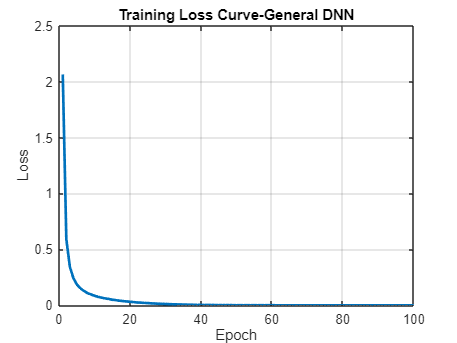

figure;
plot(loss_history, 'LineWidth', 2);
xlabel('Epoch');
ylabel('Loss');
title('Training Loss Curve-General DNN');
grid on;

Z1 = W1*X_test + b1;
A1 = max(0, Z1);
Z2 = W2*A1 + b2;
A2 = max(0, Z2);
Z3 = W3*A2 + b3;
[~, predictions] = max(Z3, [], 1);
predictions = predictions - 1;

accuracy = mean(predictions' == y_test) * 100;
fprintf('Test Accuracy for general DNN: %.2f%%\n', accuracy);

Test Accuracy for general DNN: 97.74%


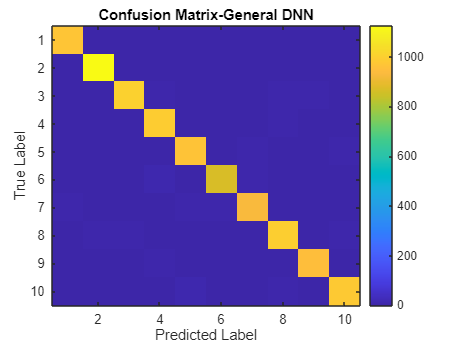

conf_mat = zeros(10,10);
for i = 1:length(y_test)
    true_label = y_test(i) + 1;
    pred_label = predictions(i) + 1;
    conf_mat(true_label, pred_label) = conf_mat(true_label, pred_label) + 1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted Label');
ylabel('True Label');
title('Confusion Matrix-General DNN');

# **Learning rate- 1e-2**

rng(1);
W1 = 0.01 * randn(128, 784);
b1 = zeros(128, 1);
W2 = 0.01 * randn(64, 128);
b2 = zeros(64, 1);
W3 = 0.01 * randn(10, 64);
b3 = zeros(10, 1);

epochs = 100;
batch_size = 128;
lr = 1e-2;
num_samples = size(X_train, 2);
num_batches = floor(num_samples / batch_size);
loss_history = zeros(epochs, 1);

for epoch = 1:epochs
    perm = randperm(num_samples);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:, idx);
        Y = Y_train(:, idx);
        m = size(X,2);
        Z1 = W1*X + b1;
        A1 = max(0, Z1);
        Z2 = W2*A1 + b2;
        A2 = max(0, Z2);
        Z3 = W3*A2 + b3;
        Z3 = Z3 - max(Z3, [], 1);
        expZ = exp(Z3);
        Y_hat = expZ ./ sum(expZ,1);
        loss = -sum(sum(Y .* log(Y_hat))) / m;
        epoch_loss = epoch_loss + loss;
        dZ3 = Y_hat - Y;
        dW3 = (1/m) * dZ3 * A2';
        db3 = (1/m) * sum(dZ3,2);
        dA2 = W3' * dZ3;
        dZ2 = dA2 .* (Z2 > 0);
        dW2 = (1/m) * dZ2 * A1';
        db2 = (1/m) * sum(dZ2,2);
        dA1 = W2' * dZ2;
        dZ1 = dA1 .* (Z1 > 0);
        dW1 = (1/m) * dZ1 * X';
        db1 = (1/m) * sum(dZ1,2);
        W3 = W3 - lr*dW3;  b3 = b3 - lr*db3;
        W2 = W2 - lr*dW2;  b2 = b2 - lr*db2;
        W1 = W1 - lr*dW1;  b1 = b1 - lr*db1;
    end
    loss_history(epoch) = epoch_loss / num_batches;
    fprintf('Epoch %d/%d | Loss: %.4f\n', epoch, epochs, loss_history(epoch));
end

Epoch 1/100 | Loss: 2.3020
Epoch 2/100 | Loss: 2.3012
Epoch 3/100 | Loss: 2.3005
Epoch 4/100 | Loss: 2.2996
Epoch 5/100 | Loss: 2.2978
Epoch 6/100 | Loss: 2.2916
Epoch 7/100 | Loss: 2.2479
Epoch 8/100 | Loss: 1.9705
Epoch 9/100 | Loss: 1.4551
Epoch 10/100 | Loss: 1.0161
Epoch 11/100 | Loss: 0.7701
Epoch 12/100 | Loss: 0.6658
Epoch 13/100 | Loss: 0.6158
Epoch 14/100 | Loss: 0.5824
Epoch 15/100 | Loss: 0.5543
Epoch 16/100 | Loss: 0.5290
Epoch 17/100 | Loss: 0.5032
Epoch 18/100 | Loss: 0.4741
Epoch 19/100 | Loss: 0.4444
Epoch 20/100 | Loss: 0.4185
Epoch 21/100 | Loss: 0.3973
Epoch 22/100 | Loss: 0.3799
Epoch 23/100 | Loss: 0.3645
Epoch 24/100 | Loss: 0.3511
Epoch 25/100 | Loss: 0.3384
Epoch 26/100 | Loss: 0.3270
Epoch 27/100 | Loss: 0.3154
Epoch 28/100 | Loss: 0.3049
Epoch 29/100 | Loss: 0.2950
Epoch 30/100 | Loss: 0.2856
Epoch 31/100 | Loss: 0.2764
Epoch 32/100 | Loss: 0.2670
Epoch 33/100 | Loss: 0.2585
Epoch 34/100 | Loss: 0.2503
Epoch 35/100 | Loss: 0.2429
Epoch 36/100 | Loss: 0.2353
E

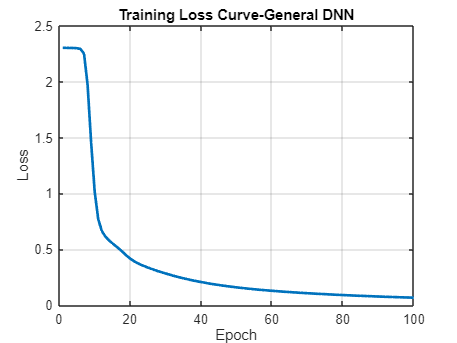

figure;
plot(loss_history, 'LineWidth', 2);
xlabel('Epoch');
ylabel('Loss');
title('Training Loss Curve-General DNN');
grid on;

Z1 = W1*X_test + b1;
A1 = max(0, Z1);
Z2 = W2*A1 + b2;
A2 = max(0, Z2);
Z3 = W3*A2 + b3;
[~, predictions] = max(Z3, [], 1);
predictions = predictions - 1;

accuracy = mean(predictions' == y_test) * 100;
fprintf('Test Accuracy for general DNN: %.2f%%\n', accuracy);

Test Accuracy for general DNN: 97.10%


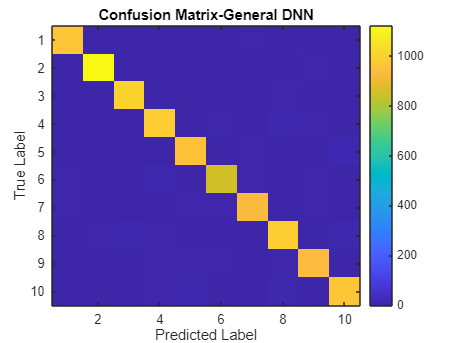

conf_mat = zeros(10,10);
for i = 1:length(y_test)
    true_label = y_test(i) + 1;
    pred_label = predictions(i) + 1;
    conf_mat(true_label, pred_label) = conf_mat(true_label, pred_label) + 1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted Label');
ylabel('True Label');
title('Confusion Matrix-General DNN');

# **Learning rate- 1e-3**

rng(1);
W1 = 0.01 * randn(128, 784);
b1 = zeros(128, 1);
W2 = 0.01 * randn(64, 128);
b2 = zeros(64, 1);
W3 = 0.01 * randn(10, 64);
b3 = zeros(10, 1);

epochs = 100;
batch_size = 128;
lr = 1e-3;
num_samples = size(X_train, 2);
num_batches = floor(num_samples / batch_size);
loss_history = zeros(epochs, 1);

for epoch = 1:epochs
    perm = randperm(num_samples);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:, idx);
        Y = Y_train(:, idx);
        m = size(X,2);
        Z1 = W1*X + b1;
        A1 = max(0, Z1);
        Z2 = W2*A1 + b2;
        A2 = max(0, Z2);
        Z3 = W3*A2 + b3;
        Z3 = Z3 - max(Z3, [], 1);
        expZ = exp(Z3);
        Y_hat = expZ ./ sum(expZ,1);
        loss = -sum(sum(Y .* log(Y_hat))) / m;
        epoch_loss = epoch_loss + loss;
        dZ3 = Y_hat - Y;
        dW3 = (1/m) * dZ3 * A2';
        db3 = (1/m) * sum(dZ3,2);
        dA2 = W3' * dZ3;
        dZ2 = dA2 .* (Z2 > 0);
        dW2 = (1/m) * dZ2 * A1';
        db2 = (1/m) * sum(dZ2,2);
        dA1 = W2' * dZ2;
        dZ1 = dA1 .* (Z1 > 0);
        dW1 = (1/m) * dZ1 * X';
        db1 = (1/m) * sum(dZ1,2);
        W3 = W3 - lr*dW3;  b3 = b3 - lr*db3;
        W2 = W2 - lr*dW2;  b2 = b2 - lr*db2;
        W1 = W1 - lr*dW1;  b1 = b1 - lr*db1;
    end
    loss_history(epoch) = epoch_loss / num_batches;
    fprintf('Epoch %d/%d | Loss: %.4f\n', epoch, epochs, loss_history(epoch));
end

Epoch 1/100 | Loss: 2.3025
Epoch 2/100 | Loss: 2.3024
Epoch 3/100 | Loss: 2.3022
Epoch 4/100 | Loss: 2.3021
Epoch 5/100 | Loss: 2.3020
Epoch 6/100 | Loss: 2.3019
Epoch 7/100 | Loss: 2.3018
Epoch 8/100 | Loss: 2.3017
Epoch 9/100 | Loss: 2.3016
Epoch 10/100 | Loss: 2.3015
Epoch 11/100 | Loss: 2.3014
Epoch 12/100 | Loss: 2.3014
Epoch 13/100 | Loss: 2.3013
Epoch 14/100 | Loss: 2.3012
Epoch 15/100 | Loss: 2.3012
Epoch 16/100 | Loss: 2.3011
Epoch 17/100 | Loss: 2.3010
Epoch 18/100 | Loss: 2.3010
Epoch 19/100 | Loss: 2.3009
Epoch 20/100 | Loss: 2.3008
Epoch 21/100 | Loss: 2.3008
Epoch 22/100 | Loss: 2.3007
Epoch 23/100 | Loss: 2.3007
Epoch 24/100 | Loss: 2.3006
Epoch 25/100 | Loss: 2.3005
Epoch 26/100 | Loss: 2.3005
Epoch 27/100 | Loss: 2.3004
Epoch 28/100 | Loss: 2.3003
Epoch 29/100 | Loss: 2.3002
Epoch 30/100 | Loss: 2.3002
Epoch 31/100 | Loss: 2.3001
Epoch 32/100 | Loss: 2.3000
Epoch 33/100 | Loss: 2.2999
Epoch 34/100 | Loss: 2.2998
Epoch 35/100 | Loss: 2.2997
Epoch 36/100 | Loss: 2.2996
E

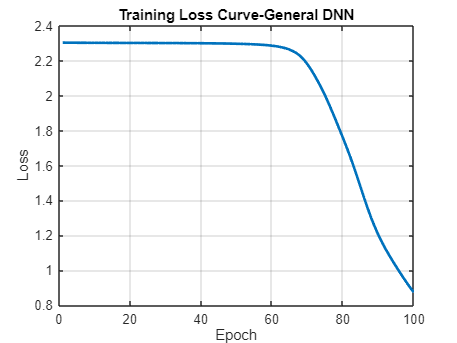

figure;
plot(loss_history, 'LineWidth', 2);
xlabel('Epoch');
ylabel('Loss');
title('Training Loss Curve-General DNN');
grid on;

Z1 = W1*X_test + b1;
A1 = max(0, Z1);
Z2 = W2*A1 + b2;
A2 = max(0, Z2);
Z3 = W3*A2 + b3;
[~, predictions] = max(Z3, [], 1);
predictions = predictions - 1;

accuracy = mean(predictions' == y_test) * 100;
fprintf('Test Accuracy for general DNN: %.2f%%\n', accuracy);

Test Accuracy for general DNN: 74.17%


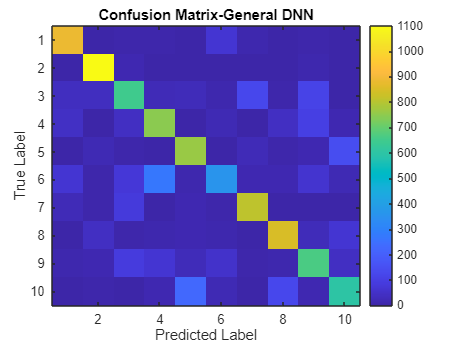

conf_mat = zeros(10,10);
for i = 1:length(y_test)
    true_label = y_test(i) + 1;
    pred_label = predictions(i) + 1;
    conf_mat(true_label, pred_label) = conf_mat(true_label, pred_label) + 1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted Label');
ylabel('True Label');
title('Confusion Matrix-General DNN');

# **Learning rate- 1e-4**

rng(1);
W1 = 0.01 * randn(128, 784);
b1 = zeros(128, 1);
W2 = 0.01 * randn(64, 128);
b2 = zeros(64, 1);
W3 = 0.01 * randn(10, 64);
b3 = zeros(10, 1);

epochs = 100;
batch_size = 128;
lr = 1e-4;
num_samples = size(X_train, 2);
num_batches = floor(num_samples / batch_size);
loss_history = zeros(epochs, 1);

for epoch = 1:epochs
    perm = randperm(num_samples);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:, idx);
        Y = Y_train(:, idx);
        m = size(X,2);
        Z1 = W1*X + b1;
        A1 = max(0, Z1);
        Z2 = W2*A1 + b2;
        A2 = max(0, Z2);
        Z3 = W3*A2 + b3;
        Z3 = Z3 - max(Z3, [], 1);
        expZ = exp(Z3);
        Y_hat = expZ ./ sum(expZ,1);
        loss = -sum(sum(Y .* log(Y_hat))) / m;
        epoch_loss = epoch_loss + loss;
        dZ3 = Y_hat - Y;
        dW3 = (1/m) * dZ3 * A2';
        db3 = (1/m) * sum(dZ3,2);
        dA2 = W3' * dZ3;
        dZ2 = dA2 .* (Z2 > 0);
        dW2 = (1/m) * dZ2 * A1';
        db2 = (1/m) * sum(dZ2,2);
        dA1 = W2' * dZ2;
        dZ1 = dA1 .* (Z1 > 0);
        dW1 = (1/m) * dZ1 * X';
        db1 = (1/m) * sum(dZ1,2);
        W3 = W3 - lr*dW3;  b3 = b3 - lr*db3;
        W2 = W2 - lr*dW2;  b2 = b2 - lr*db2;
        W1 = W1 - lr*dW1;  b1 = b1 - lr*db1;
    end
    loss_history(epoch) = epoch_loss / num_batches;
    fprintf('Epoch %d/%d | Loss: %.4f\n', epoch, epochs, loss_history(epoch));
end

Epoch 1/100 | Loss: 2.3026
Epoch 2/100 | Loss: 2.3026
Epoch 3/100 | Loss: 2.3026
Epoch 4/100 | Loss: 2.3026
Epoch 5/100 | Loss: 2.3025
Epoch 6/100 | Loss: 2.3025
Epoch 7/100 | Loss: 2.3025
Epoch 8/100 | Loss: 2.3025
Epoch 9/100 | Loss: 2.3025
Epoch 10/100 | Loss: 2.3025
Epoch 11/100 | Loss: 2.3024
Epoch 12/100 | Loss: 2.3024
Epoch 13/100 | Loss: 2.3024
Epoch 14/100 | Loss: 2.3024
Epoch 15/100 | Loss: 2.3024
Epoch 16/100 | Loss: 2.3024
Epoch 17/100 | Loss: 2.3024
Epoch 18/100 | Loss: 2.3023
Epoch 19/100 | Loss: 2.3023
Epoch 20/100 | Loss: 2.3023
Epoch 21/100 | Loss: 2.3023
Epoch 22/100 | Loss: 2.3023
Epoch 23/100 | Loss: 2.3023
Epoch 24/100 | Loss: 2.3023
Epoch 25/100 | Loss: 2.3022
Epoch 26/100 | Loss: 2.3022
Epoch 27/100 | Loss: 2.3022
Epoch 28/100 | Loss: 2.3022
Epoch 29/100 | Loss: 2.3022
Epoch 30/100 | Loss: 2.3022
Epoch 31/100 | Loss: 2.3022
Epoch 32/100 | Loss: 2.3022
Epoch 33/100 | Loss: 2.3021
Epoch 34/100 | Loss: 2.3021
Epoch 35/100 | Loss: 2.3021
Epoch 36/100 | Loss: 2.3021
E

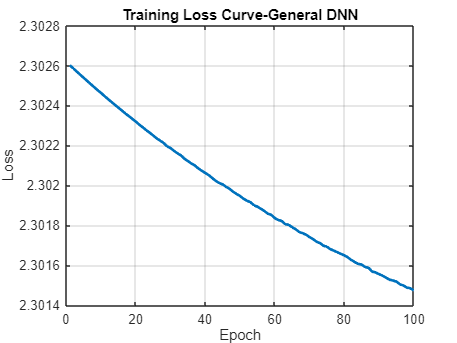

figure;
plot(loss_history, 'LineWidth', 2);
xlabel('Epoch');
ylabel('Loss');
title('Training Loss Curve-General DNN');
grid on;

Z1 = W1*X_test + b1;
A1 = max(0, Z1);
Z2 = W2*A1 + b2;
A2 = max(0, Z2);
Z3 = W3*A2 + b3;
[~, predictions] = max(Z3, [], 1);
predictions = predictions - 1;

accuracy = mean(predictions' == y_test) * 100;
fprintf('Test Accuracy for general DNN: %.2f%%\n', accuracy);

Test Accuracy for general DNN: 11.35%


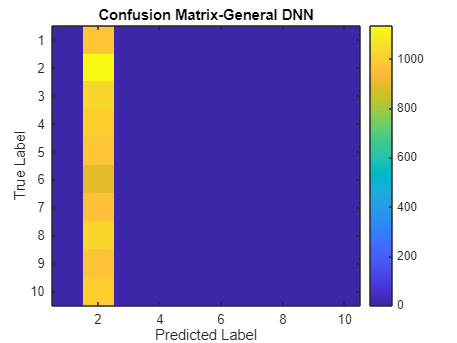

conf_mat = zeros(10,10);
for i = 1:length(y_test)
    true_label = y_test(i) + 1;
    pred_label = predictions(i) + 1;
    conf_mat(true_label, pred_label) = conf_mat(true_label, pred_label) + 1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted Label');
ylabel('True Label');
title('Confusion Matrix-General DNN');

# **Learning rate- 1e-5**

rng(1);
W1 = 0.01 * randn(128, 784);
b1 = zeros(128, 1);
W2 = 0.01 * randn(64, 128);
b2 = zeros(64, 1);
W3 = 0.01 * randn(10, 64);
b3 = zeros(10, 1);

epochs = 100;
batch_size = 128;
lr = 1e-5;
num_samples = size(X_train, 2);
num_batches = floor(num_samples / batch_size);
loss_history = zeros(epochs, 1);

for epoch = 1:epochs
    perm = randperm(num_samples);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:, idx);
        Y = Y_train(:, idx);
        m = size(X,2);
        Z1 = W1*X + b1;
        A1 = max(0, Z1);
        Z2 = W2*A1 + b2;
        A2 = max(0, Z2);
        Z3 = W3*A2 + b3;
        Z3 = Z3 - max(Z3, [], 1);
        expZ = exp(Z3);
        Y_hat = expZ ./ sum(expZ,1);
        loss = -sum(sum(Y .* log(Y_hat))) / m;
        epoch_loss = epoch_loss + loss;
        dZ3 = Y_hat - Y;
        dW3 = (1/m) * dZ3 * A2';
        db3 = (1/m) * sum(dZ3,2);
        dA2 = W3' * dZ3;
        dZ2 = dA2 .* (Z2 > 0);
        dW2 = (1/m) * dZ2 * A1';
        db2 = (1/m) * sum(dZ2,2);
        dA1 = W2' * dZ2;
        dZ1 = dA1 .* (Z1 > 0);
        dW1 = (1/m) * dZ1 * X';
        db1 = (1/m) * sum(dZ1,2);
        W3 = W3 - lr*dW3;  b3 = b3 - lr*db3;
        W2 = W2 - lr*dW2;  b2 = b2 - lr*db2;
        W1 = W1 - lr*dW1;  b1 = b1 - lr*db1;
    end
    loss_history(epoch) = epoch_loss / num_batches;
    fprintf('Epoch %d/%d | Loss: %.4f\n', epoch, epochs, loss_history(epoch));
end

Epoch 1/100 | Loss: 2.3026
Epoch 2/100 | Loss: 2.3026
Epoch 3/100 | Loss: 2.3026
Epoch 4/100 | Loss: 2.3026
Epoch 5/100 | Loss: 2.3026
Epoch 6/100 | Loss: 2.3026
Epoch 7/100 | Loss: 2.3026
Epoch 8/100 | Loss: 2.3026
Epoch 9/100 | Loss: 2.3026
Epoch 10/100 | Loss: 2.3026
Epoch 11/100 | Loss: 2.3026
Epoch 12/100 | Loss: 2.3026
Epoch 13/100 | Loss: 2.3026
Epoch 14/100 | Loss: 2.3026
Epoch 15/100 | Loss: 2.3026
Epoch 16/100 | Loss: 2.3026
Epoch 17/100 | Loss: 2.3026
Epoch 18/100 | Loss: 2.3026
Epoch 19/100 | Loss: 2.3026
Epoch 20/100 | Loss: 2.3026
Epoch 21/100 | Loss: 2.3026
Epoch 22/100 | Loss: 2.3026
Epoch 23/100 | Loss: 2.3026
Epoch 24/100 | Loss: 2.3026
Epoch 25/100 | Loss: 2.3026
Epoch 26/100 | Loss: 2.3026
Epoch 27/100 | Loss: 2.3026
Epoch 28/100 | Loss: 2.3026
Epoch 29/100 | Loss: 2.3026
Epoch 30/100 | Loss: 2.3026
Epoch 31/100 | Loss: 2.3026
Epoch 32/100 | Loss: 2.3026
Epoch 33/100 | Loss: 2.3026
Epoch 34/100 | Loss: 2.3026
Epoch 35/100 | Loss: 2.3026
Epoch 36/100 | Loss: 2.3026
E

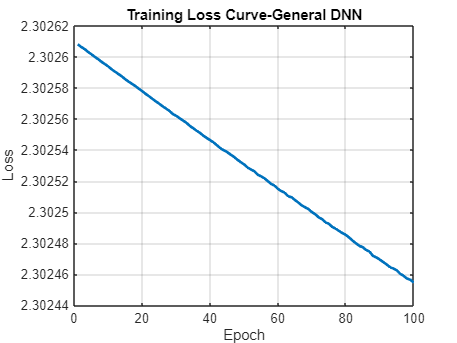

figure;
plot(loss_history, 'LineWidth', 2);
xlabel('Epoch');
ylabel('Loss');
title('Training Loss Curve-General DNN');
grid on;

Z1 = W1*X_test + b1;
A1 = max(0, Z1);
Z2 = W2*A1 + b2;
A2 = max(0, Z2);
Z3 = W3*A2 + b3;
[~, predictions] = max(Z3, [], 1);
predictions = predictions - 1;

accuracy = mean(predictions' == y_test) * 100;
fprintf('Test Accuracy for general DNN: %.2f%%\n', accuracy);

Test Accuracy for general DNN: 11.35%


conf_mat = zeros(10,10);
for i = 1:length(y_test)
    true_label = y_test(i) + 1;
    pred_label = predictions(i) + 1;
    conf_mat(true_label, pred_label) = conf_mat(true_label, pred_label) + 1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted Label');
ylabel('True Label');
title('Confusion Matrix-General DNN');

# **Learning rate- 1e-6**

rng(1);
W1 = 0.01 * randn(128, 784);
b1 = zeros(128, 1);
W2 = 0.01 * randn(64, 128);
b2 = zeros(64, 1);
W3 = 0.01 * randn(10, 64);
b3 = zeros(10, 1);

epochs = 100;
batch_size = 128;
lr = 1e-6;
num_samples = size(X_train, 2);
num_batches = floor(num_samples / batch_size);
loss_history = zeros(epochs, 1);

for epoch = 1:epochs
    perm = randperm(num_samples);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:, idx);
        Y = Y_train(:, idx);
        m = size(X,2);
        Z1 = W1*X + b1;
        A1 = max(0, Z1);
        Z2 = W2*A1 + b2;
        A2 = max(0, Z2);
        Z3 = W3*A2 + b3;
        Z3 = Z3 - max(Z3, [], 1);
        expZ = exp(Z3);
        Y_hat = expZ ./ sum(expZ,1);
        loss = -sum(sum(Y .* log(Y_hat))) / m;
        epoch_loss = epoch_loss + loss;
        dZ3 = Y_hat - Y;
        dW3 = (1/m) * dZ3 * A2';
        db3 = (1/m) * sum(dZ3,2);
        dA2 = W3' * dZ3;
        dZ2 = dA2 .* (Z2 > 0);
        dW2 = (1/m) * dZ2 * A1';
        db2 = (1/m) * sum(dZ2,2);
        dA1 = W2' * dZ2;
        dZ1 = dA1 .* (Z1 > 0);
        dW1 = (1/m) * dZ1 * X';
        db1 = (1/m) * sum(dZ1,2);
        W3 = W3 - lr*dW3;  b3 = b3 - lr*db3;
        W2 = W2 - lr*dW2;  b2 = b2 - lr*db2;
        W1 = W1 - lr*dW1;  b1 = b1 - lr*db1;
    end
    loss_history(epoch) = epoch_loss / num_batches;
    fprintf('Epoch %d/%d | Loss: %.4f\n', epoch, epochs, loss_history(epoch));
end

Epoch 1/100 | Loss: 2.3026
Epoch 2/100 | Loss: 2.3026
Epoch 3/100 | Loss: 2.3026
Epoch 4/100 | Loss: 2.3026
Epoch 5/100 | Loss: 2.3026
Epoch 6/100 | Loss: 2.3026
Epoch 7/100 | Loss: 2.3026
Epoch 8/100 | Loss: 2.3026
Epoch 9/100 | Loss: 2.3026
Epoch 10/100 | Loss: 2.3026
Epoch 11/100 | Loss: 2.3026
Epoch 12/100 | Loss: 2.3026
Epoch 13/100 | Loss: 2.3026
Epoch 14/100 | Loss: 2.3026
Epoch 15/100 | Loss: 2.3026
Epoch 16/100 | Loss: 2.3026
Epoch 17/100 | Loss: 2.3026
Epoch 18/100 | Loss: 2.3026
Epoch 19/100 | Loss: 2.3026
Epoch 20/100 | Loss: 2.3026
Epoch 21/100 | Loss: 2.3026
Epoch 22/100 | Loss: 2.3026
Epoch 23/100 | Loss: 2.3026
Epoch 24/100 | Loss: 2.3026
Epoch 25/100 | Loss: 2.3026
Epoch 26/100 | Loss: 2.3026
Epoch 27/100 | Loss: 2.3026
Epoch 28/100 | Loss: 2.3026
Epoch 29/100 | Loss: 2.3026
Epoch 30/100 | Loss: 2.3026
Epoch 31/100 | Loss: 2.3026
Epoch 32/100 | Loss: 2.3026
Epoch 33/100 | Loss: 2.3026
Epoch 34/100 | Loss: 2.3026
Epoch 35/100 | Loss: 2.3026
Epoch 36/100 | Loss: 2.3026
E

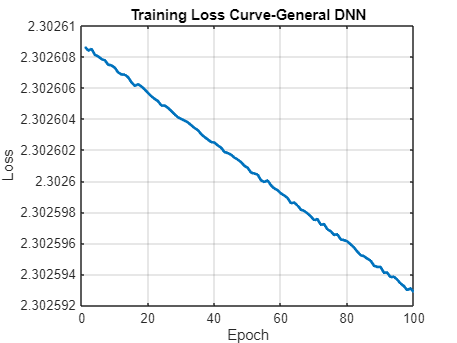

figure;
plot(loss_history, 'LineWidth', 2);
xlabel('Epoch');
ylabel('Loss');
title('Training Loss Curve-General DNN');
grid on;

Z1 = W1*X_test + b1;
A1 = max(0, Z1);
Z2 = W2*A1 + b2;
A2 = max(0, Z2);
Z3 = W3*A2 + b3;
[~, predictions] = max(Z3, [], 1);
predictions = predictions - 1;

accuracy = mean(predictions' == y_test) * 100;
fprintf('Test Accuracy for general DNN: %.2f%%\n', accuracy);

Test Accuracy for general DNN: 8.48%


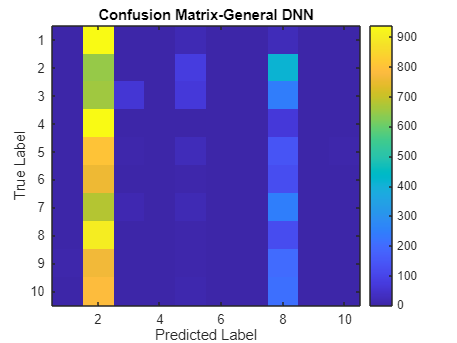

conf_mat = zeros(10,10);
for i = 1:length(y_test)
    true_label = y_test(i) + 1;
    pred_label = predictions(i) + 1;
    conf_mat(true_label, pred_label) = conf_mat(true_label, pred_label) + 1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted Label');
ylabel('True Label');
title('Confusion Matrix-General DNN');